# Homework 2

Completed By: Ryan Campbell and Christian Molina

## Problem 1

(17 points) (T) Suppose that $x_0 = \frac{1}{4}, x_1 = \frac{1}{2}, x_2 = 1,\ \text{and}\ x_3 = 2$.

        (a) Use divided differences to compute the newton form of the third degree polynomial such that $p(x_0) = 1, p(x_1) = 2, p(x_2) = 5, \ \text{and} \ p(x_3) = -1$.

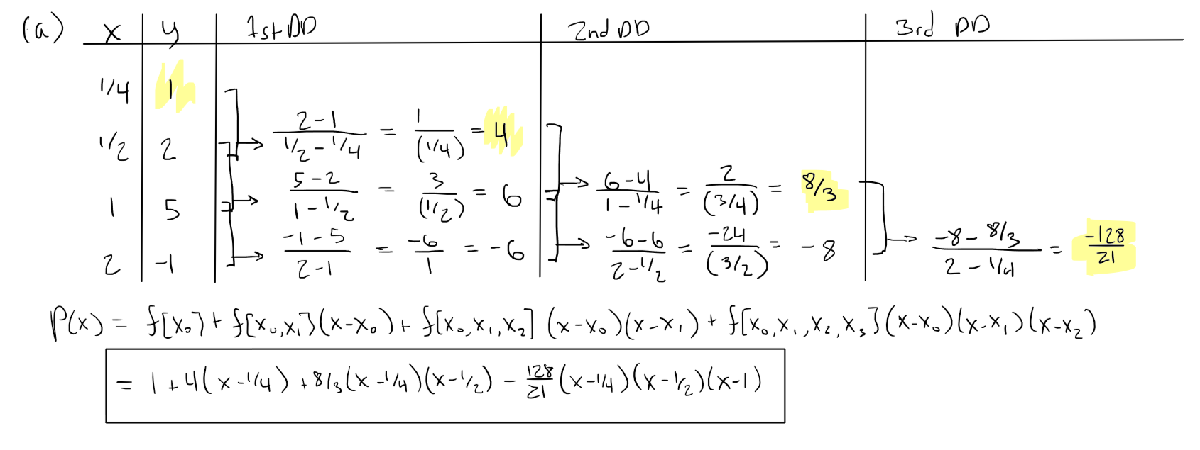

        (b) For the same data, write the Lagrange interpolating polynomial.

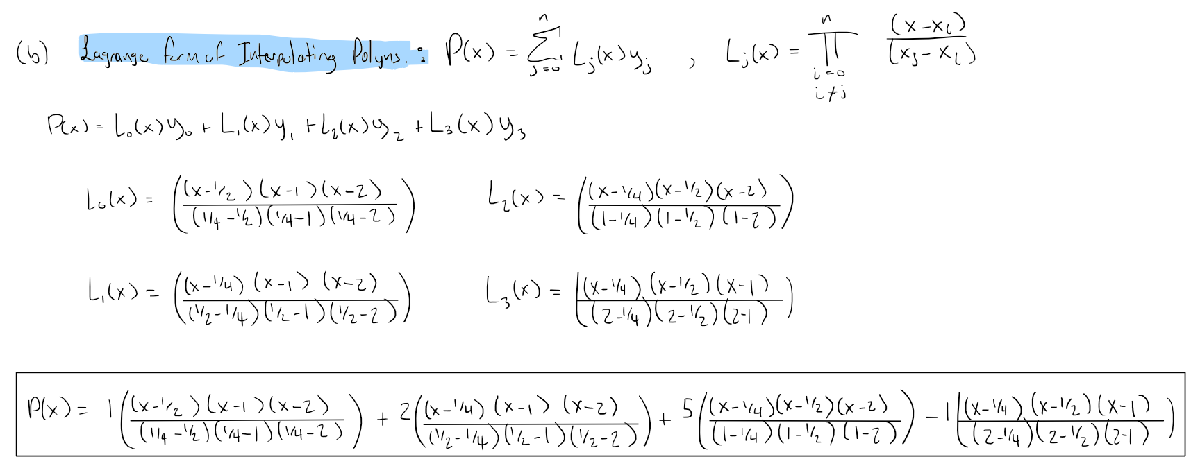

        (c) Show that these two forms are the same polynomial.

## Problem 2

(27 points) Given the points $(x_i,y_i)$ for $i = 0 \dots n$ the Newton form of the interpolating polynomial is

$p(x) = a_0 + a_1(x-x_0)+\cdots+a_n(x-x_0)(x-x_1)\cdots(x-x_{n-1})$.

The textbook provides code for computing the coeffients by a divided difference table and evaluating the polynomial. I provided this code on the class website. 															

(a)  Compute the coefficients of the Newton form of the interpolating polynomial for the fifth degree polynomial that interpolates $f(x) = \cos(2\pi x)$ at the points $x_j = j/5$ for $j = 0, \dots ,5$. Display the results in a table. 	

% Christian Molina
% MAT128A - HW 2a
yi = [];
xi = (0:5)/5;                   % j is not defined, instead we represent j as the range (0:5) in xi.
yi = [yi,cos(2*pi*xi)];

[~,table] = divdif (xi, yi)     % Displays table of values

table =     1.0000         0         0         0         0         0
    0.3090   -3.4549         0         0         0         0
   -0.8090   -5.5902   -5.3381         0         0         0
   -0.8090   -0.0000   13.9754   32.1893         0         0
    0.3090    5.5902   13.9754   -0.0000  -40.2366         0
    1.0000    3.4549   -5.3381  -32.1893  -40.2366    0.0000


(b)  Make a plot of $f(x)$ and the interpolating polynomial, $p(x)$, from part $(a)$ on the same axes for $0\le x\le 1$. Plot the difference of $f$ and $p$ for $0\le x\le 1$. 

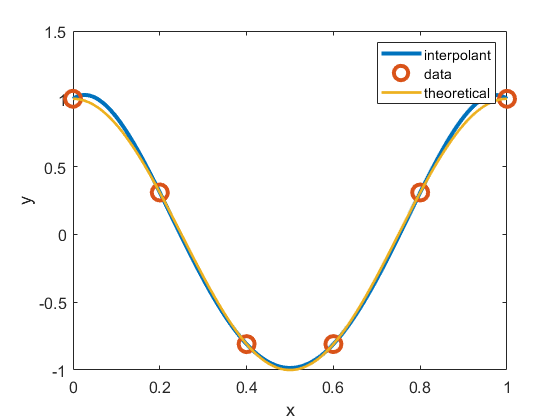

[coef,~] = divdif (xi, yi);     % Used in calculation of the plot below for problem 2b
xd = linspace(0,1,1000);
yt = evalnewt (xd, xi, coef);

figure(1);
hp=plot(xd,yt,xi,yi,'o');
set(hp,'linewidth',3,'markersize',12);
set(gca,'fontsize',12);
xlabel('x');
ylabel('y');
xlim([0 1])
ylim([-1 1.5])
hold on;
tp=plot(xd,cos(2*pi*xd));
set(tp,'linewidth',2,'markersize',12);
legend('interpolant','data','theoretical');						

(c)  Estimate the maximum of $|f(x) - p(x)|$ on the interval $[0, 1]$ by evaluating $f$ and $p$ for a large number of points between $0$ and $1$.

est_max = max(abs(cos(2*pi*xd) - yt));
disp(['Maximum difference between f(x) and p(x): ',num2str(est_max)]) 								

Maximum difference between f(x) and p(x): 0.06261


(d)  Evaluate $p(1.5)$, $p(2.0)$, and $p(2.5)$ and report the results. Why are the values of $p$ so different from the values of $f$ at these points compared to points in $[0, 1]$? 

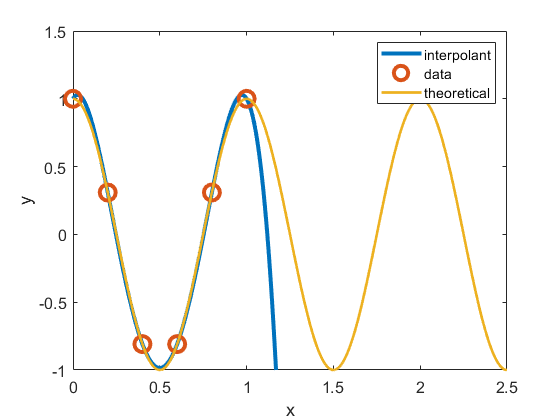

[coef,~] = divdif (xi, yi);     % Used in calculation of the plot below for problem 2b
xd = linspace(0,3,1000);
yt = evalnewt (xd, xi, coef);

figure(2);
hp=plot(xd,yt,xi,yi,'o');
set(hp,'linewidth',3,'markersize',12);
set(gca,'fontsize',12);
xlabel('x');
ylabel('y');
xlim([0 2.5])
ylim([-1 1.5])
hold on;
tp=plot(xd,cos(2*pi*xd));
set(tp,'linewidth',2,'markersize',12);
legend('interpolant','data','theoretical');

By expanding the values of x to [0,3], we can see that P(x) begins to lose accuracy. This is due to the limited amount of terms in P(x) that are only interpolated up to a 5th degree polynomial. If we were to increase the amount of values we calculate in divided differences - say 10 values - the polynomial terms will increase to a 10th degree polynomial. This allows P(x) to accurately represent f(x) for greater values of x. 

## Problem 3	

(18 points) (T) Suppose you wish to find a polynomial p that satisfies the conditions 

$p(0) = 0$, $p\prime (0) = 0$, $p\prime \prime (0) = 0$, $p(1) = 1$, $p\prime (1) = 0$, $p\prime \prime (1) = 0$

What degree polynomial satisfies these conditions? Prove your claim. (It is not necessary that you find $p(x)$, but finding it would be one way to prove it.) 						

        *In order for *$p(x)$* to satisfy *$p\prime (0) = 0$*, *$p\prime \prime (0) = 0$*, *$p\prime (1) = 0$*, and *$p\prime \prime (1) = 0$*, we need a polynomial that is at least horizontal at *$x=0$* and *$x=1$* so that the first and second derivative at each point are zero. In addition, we require it to pass through the points *$(0,0)$* and *$(1,1)$* so that *$p(0) = 0$*, and *$p(1) = 1$* are satisfied. Such a polynomial implies we need at least a 3rd degree polynomial which has local maximums or minimums at *$x=0$* and *$x=1$*.*

## Problem 4

(35 points) Given the nodes


$$a=x_0 <x_1 <\cdots <x_n =b,$$
 

let $S$ be the piecewise Hermite cubic interpolant of $f$ at these nodes. That is $S$ interpolates $f$ and $f\prime $ at these nodes, and on each subinterval $[x_i,x_{i+1}]$, $S$ coincides with a cubic polynomial $S_i (x)$.

        (a) Let $h = max_i(x_{i+1} - x_i)$ and assume that $f$ has at least four continuous derivatives on $[a, b]$. Show that


$$|f(x) - S(x)| \leq \frac{h^4}{384} \max_{\xi \in [a,b]} |f^{(4)}(\xi)|$$


        (b) (T) On the interval $[x_i,x_{i+1}]$ let $S_i$ be represented as 


$$S_i(x)=a_i +b(x-x_i)+c(x-x_i)^2 +d(x-x_i)^3.$$


            Derive expressions for $a_i, b_i, c_i, \ \text{and} \ d_i$ in terms of$h_i = x_{i+1} -x_i, f_i = f(x_i), f_i\prime  = f\prime (x_i), f_{i+1} = f(x_{i+1}), \ \text{and} \ f\prime_{i+1} = f\prime (x_{i+1})$. 

        (c) Evaluating $S$ requires the location of the nodes ($x_j$'s) and the coefficients computed in the previous part. For easy evaluation, the coefficients can be stored in an $(n+1)$ by $4$ array. For example, let $P$ be an $(n + 1)$ by $4$ array with elements defined as$P_{i,1} = a_i, P_{i,2} = b_i, P_{i,3} = c_i, \ \text{and} \ P_{i,4} = d_i$. Write a routine which takes as input the three arrays corresponding to the location of the nodes, the function values at these nodes, and the derivative values at the nodes, and it returns the array of coefficients, **P**. Use your routine to compute the coefficients defining $S$ for the function $f(x) = \cos(2\pi x)$ at the nodes $x_i = i/5$ for $i = 0, \dots , 5$. Display the resulting coefficients in a table.

        (d) Write a routine which takes as input the location of the nodes, the array of coefficients, and an evaluation point, $x$, and returns the value of $S(x)$. Let $f(x) = \cos(2\pi x)$ and let $x_i = i/n$ for $i = 0,1, \dots ,n$ be the $n+1$ equally spaced points on $[0,1]$. For a range of $n$ values use your code to estimate $\max_{x\in [0,1]} |f(x) - S(x)|$ by evaluating $f$ and $S$ on a large set of values in $[0, 1]$. Display your results in a table and/or graph (use log-log plot). Discuss how your results demonstrate $\mathcal{O}(h^4)$ convergence. 

## Problem 5

(35 points) At the end of this assignment, code is given that takes as input vectors $x$ and $y$, and returns an array, $P$, which contains the coefficients of the natural cubic spline through the points $(x_i, y_i)$. The cubic spline is defined as $S(x) = S_i(x)$ for $x_i \le  x \le  x_{i+1}$, and

$S_i(x) = P_{i1} +P_{i2}(x-x_i) + P_{i3}(x-x_i)^2 + P_{i4}(x-x_i)^3$. 

Note that you can used your code Problem $4c$ to evaluate the spline. 

        (a) (T) In the absence of derivatives at the endpoints, one commonly uses the *not-a-knot *boundary condition rather than natural boundary conditions. If the points are indexed from $j = 0 \dots n$, then the not-a-knot condition requires that $S\prime \prime \prime (x)$ be continuous at $x_1$ and $x_{n-1}$. For $S_i(x) = a_i + b_i(x - x_i) + c_i(x - x_i)^2 + d_i(x - x_i)^3$, our textbook derives the system of linear equations for the values of $c_i$: 


$$h_{i-1}c_{i-1} + 2(h_{i-1} + h_i)c_i + h_ic_{i+1} = \frac{3}{h_i}(a_{i+1} - a_i) - \frac{3}{h_{i-1}} (a_i - a_{i-1})$$


for $i = 1 \dots n-1$, where $h_i = x_{i+1} -x_i$. We need two more equations to be able to solve for the $c$ values. Derive the two equations that come from the not-a-knot conditions involving only $c$ values and $h$ values.

        (b) Write a routine to compute the coefficients of a cubic spline with not-a-knot boundary conditions. This requires only minor changes from the natural spline code provided. 

        (c) Plot the natural and not-a-knot splines that interpolate $f(x) = \cos(2\pi x)$ at the points $x_j = j/5$ for $j = 0, \dots , 5$. Which spline looks more like the cosine function?

        (d) For each spline, estimate the maximum error in using the spline to approximate $f(x)$ between $x = 0$ and $x = 1$. Do this by using your code to evaluate $f$ and each spline at a large number of points on $[0, 1]$ compute the maximum absolute value of the difference on these evaluation points.

## Problem 6

        (a) (35 points) Use $N = 11$ equally spaced points between $x = -1$ and $x = 1$, and plot the $N-1$-degree polynomial that interpolates


$$g(x) = \frac{1}{1+25x^2}$$


at these points for $-1 \leq x \leq 1$. Repeat for $N=21$. What is the maximum error in using these interpolating polynomials to approximate $g(x)$.

N = 11;
xN = -1:(2/N):1;
g=@(xN) (1./(1+25xN.^2));
divdif(xN,g(xN))

Invalid expression. Check for missing multiplication operator, missing or unbalanced delimiters, or other syntax error. To construct matrices, use brackets instead of parentheses.

        (b) Repeat part $(a)$, but use a piecewise Hermite cubic polynomial. 

        (c) Repeat part $(a)$, but use a not-a-knot spline. 

        (d) Repeat part $(a)$ using the points 


$$x_j = \cos\left(\frac{j}{n},\pi\right), \ j=0 \dots n,$$


instead of equally spaced points. 

        (e) Comment on your results. 

## Problem 7

(33 points) Use cubic splines to represent a curve $(x(s), y(s))$ that is in the shape of the script letter $L$ below. List the points you used to make the splines, and make a plot of your curve. You may use the provided grid to estimate the nodes by hand, or use software to help identify points on the curve. For example, in MATLAB the commands `imread`, `image`, and `ginput` could be used to aid in selecting your points. 

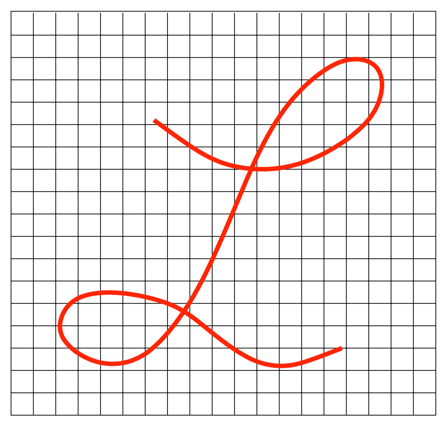

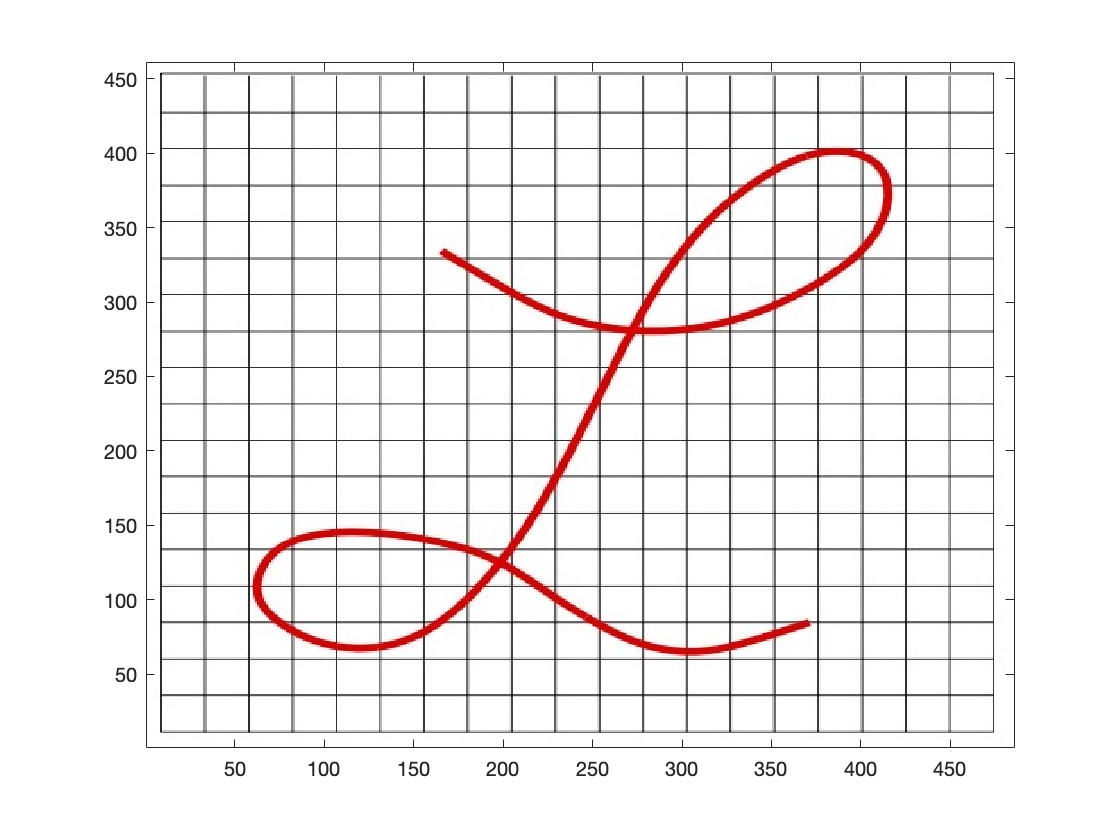

A = imread("Homework 2 - L plot.jpg");
A = image(flipud(A));       %flips image upside-down
set(gca, 'YDir', 'normal')  %adjusts y-axis direction

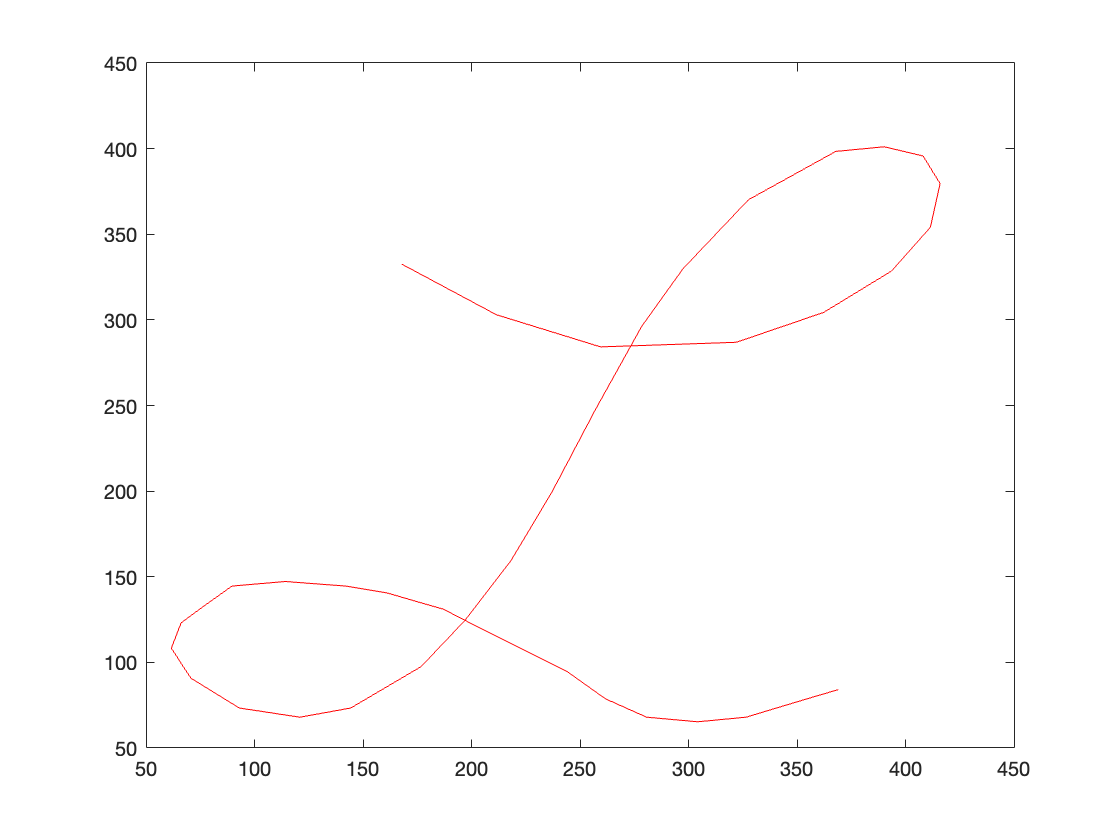

% Used to collect and store X and Y values
% [x,y] = ginput;     
% We immediately stored values as an array as not to repeat the process.
x_problem7 = x; y_problem7 = y;
xy_values_problem7 = [x_problem7, y_problem7];
x_spline = naturalspline(1:length(x_problem7),x_problem7);
y_spline = naturalspline(1:length(y_problem7),y_problem7);

plot(x_problem7,y_problem7,'-r')

*We rely on stored values in the code after picking a bunch of points on the graph from the original image. Here is an image of our result so you can see what we saw:*

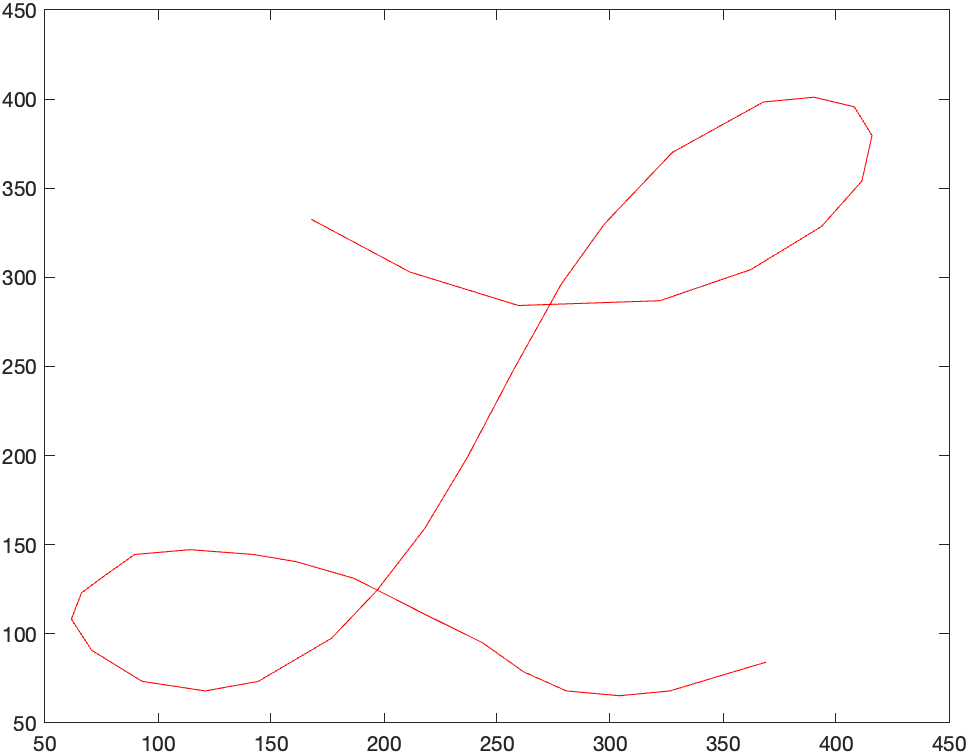

# Functions for Homework 2

% Natural spline coefficients
%   Input:      x - n by 1 vector of the nodes
%               y - n by 1 vector with the corresponding function values
%   Output:     P - n-1 by 4 matrix
%               the elements of the ith row of P give the coefficients
%               of the cubic between [x(i),x(i+1)] as
%               Si(x) = P(i,1) + P(i,2)*(x-x(i))
%                       + P(i,3)*(x-x(i))^2 + P(i,4)*(x-x(i)^3
%

function P = naturalspline(x,y);
    n = length(x);
    
    % force x and y to be column vectors
    %
    x = shiftdim(x); y = shiftdim(y);
    
    % compute the distances between the points
    %
    h = x(2:n) - x(1:n-1);
    
    % set up the tridiagonal linear system to solve
    %
    d0 = 2*(h(1:n-2)+h(2:n-1));     % diagonal
    dm1 = h(2:n-1);                 % subdiagonal, note dm1(end) not used below
    d1 = h(1:n-2);                  % superdiagonal, note d1(1) not used below
    
    % form the matrix and rhs
    %
    A = spdiags([dm1 d0 d1],-1:1,n-2,n-2);
    b = 3*(y(3:n)-y(2:n-1))./h(2:n-1) - 3*(y(2:n-1)-y(1:n-2))./h(1:n-2);
    
    % solve the linear system
    %
    z = A\b;
    
    % append the natural boundary conditions
    %
    z = [0; z; 0];
    
    % compute the coefficients
    %
    P = zeros(n-1,4);
    P(:,1) =  y(1:n-1);
    P(:,2) = (y(2:n) -y(1:n-1))./h - h.*(z(2:n)+2*z(1:n-1))/3;
    P(:,3) =  z(1:n-1);
    P(:,4) = (z(2:n)-z(1:n-1))./(3*h);
end